clc;
close all;

% Input number of channels
L = input("Enter the number of channels: ");

% Initialize arrays
g = zeros(1, L); 
t = zeros(1, L); 
g_l = zeros(1, L); 

% Collect input data
for m = 1:L
    fprintf("Channel %d\n", m);
    g(m) = input("Enter the gain of channel (dB): ");
    t(m) = input("Enter the delay of channel (us): ");
end

Channel 1
Channel 2



% Convert gains from dB to linear scale
for m = 1:L
    g_l(m) = 10^(g(m)/10);
end


% Calculate average delay
num1 = 0;
den1 = 0;
for m = 1:L
    num1 = num1 + g_l(m) * t(m);
    den1 = den1 + g_l(m);
end
T = num1 / den1;
fprintf("\nThe average delay (microseconds) is %f\n", T);


The average delay (microseconds) is 6.934316



% Calculate RMS delay spread
num2 = 0;
den2 = 0;
for m = 1:L 
    num2 = num2 + g_l(m) * (t(m) - T)^2;
    den2 = den2 + g_l(m);
end
A = num2 / den2;
a_rms = sqrt(A);
fprintf("\nThe RMS delay spread is: %f\n", a_rms);


The RMS delay spread is: 2.435159


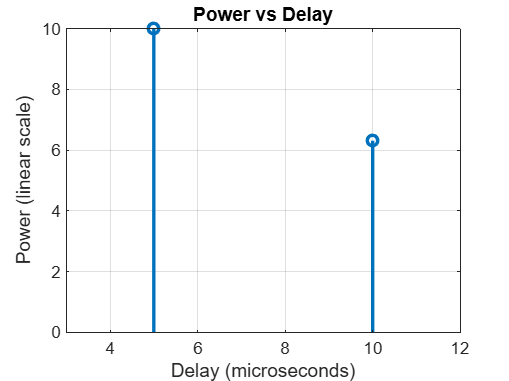


% Plot power vs delay
figure;
stem(t, g_l, 'o-', 'LineWidth', 2);
xlabel('Delay (microseconds)');
ylabel('Power (linear scale)');
title('Power vs Delay');
grid on;